c = physconst('LightSpeed');    % Скорость света
fc = 5.8e9;                     % Несущая частота (Гц)
lambda = c/fc;                  % Длина волны
R_max = 1500;                   % Максимальная дальность (м)
rangeRes = 5;                   % Разешение по дальности

modulationType = 'Sawtooth';    % {'Sawtooth', 'Triangle'}
km = 50;                       % Коэффициент запаса периода модуляции
P_tx = 1;                       % Мощность передатчика (Вт)
noiseFigure = 7;                % Коффициент шума приемника (dB)

Tm = km*range2time(R_max,c)     % Период модуляции (с)

Tm = 5.0035e-04

Bw = rangeres2bw(rangeRes,c)    % Полоса частот ЛЧМ (Гц) 100 МГц = 1,5 м

Bw = 2.9979e+07

waveformSamplingRate = 2 * Bw   % Частота дискретизации (Гц)

waveformSamplingRate = 5.9958e+07

sweepSlope = Bw/Tm              % Крутизна модуляции

sweepSlope = 5.9917e+10

T_sweep = Tm;                   % Период чирпа (с) sawtooth
N_Chirp = 1;                    % Число чирпоы в одном интервале обработки Tm

if strcmp(modulationType, 'Triangle')
    T_sweep = Tm / 2;  
    N_Chirp = 2; % Два чирпа в одном интервале обработки: 1 восходящий, 1 нисходящий
else
    modulationType = 'Up';
end

flightSpeed_max = 30; % макимальная скорость целей

% Максимальаня чатсота сигнала биений для максимальной дальности
fr_max = range2beat(R_max,sweepSlope,c)

fr_max = 5.9958e+05

fd_max = speed2dop(flightSpeed_max,lambda)

fd_max = 580.4015

fb_max = fr_max+fd_max % Максимальная частота биений

fb_max = 6.0017e+05

fs = max(2*fb_max, Bw); % Частота дескретизации расчетов
fs = round(fs * T_sweep) / T_sweep % коррекция fs для целого числа отсчетов

fs = 2.9979e+07

## Расчет антенны

% % 1 Антенная решетка
% patchElement = design(patchMicrostrip,fc);
% patchElement.Tilt = 90;
% patchElement.TiltAxis = [0 1 0];
% 
% myFigure = gcf;
% myFigure.Color = 'w';
% pattern(patchElement,fc)
% figure;
% Numfreqs = 21;
% freqsweep = unique([linspace(fc-Bw/2, fc+Bw/2, Numfreqs) fc]);
% impedance(patchElement,freqsweep);
% 
% figure;
% s = sparameters(patchElement,freqsweep);
% rfplot(s,'m-.')
% hold on
% line(freqsweep/1e9,ones(1,numel(freqsweep))*-10,'LineWidth',1.5)
% hold off

% 
% fc2 = fc+Bw/2; % Верхняя частота
% lambda_fc2 = c/fc2;
% fmcwPatchArray = phased.URA;
% fmcwPatchArray.Element = patchElement;
% Nrow = 2;
% Ncol = 4;
% fmcwPatchArray.Size = [Nrow Ncol];
% fmcwPatchArray.ElementSpacing = [0.5*lambda_fc2 0.5*lambda_fc2];
% azimuth = -180:5:180;
% elevation = -90:5:90;
% clf
% pattern(fmcwPatchArray,fc,azimuth,elevation)
% 


% % 2 АР с косинусной ДН
% cosineantenna = phased.CosineAntennaElement('FrequencyRange', frequencyRange);
% pattern(cosineantenna,fc)
% 
% Nrow = 2;
% Ncol = 4;
% antArray = phased.URA;
% antArray.Element = cosineantenna;
% antArray.Size = [Nrow Ncol];
% antArray.ElementSpacing = [0.5*lambda 0.5*lambda];
% 
% figure
% patternAzimuth(antArray,fc)
% hold on
% patternElevation(antArray,fc)
% p = polarpattern('gco');
% p.LegendLabels = {'Azimuth','Elevation'};
% beamwidth(antArray, fc);

% % 3 Ненаправленная антенна
% antenna = phased.IsotropicAntennaElement('FrequencyRange', frequencyRange);

% % 4 Гауссова ДН по заданным параметрам
% antennaElement = phased.GaussianAntennaElement("Beamwidth",antBeamwidth,"FrequencyRange",frequencyRange);

% Plot the beamwidth to verify that it matches the expected antenna beamwidth
% beamwidth(fmcwPatchArray, fc, azVec, elVec);
% pattern(fmcwPatchArray,fc,  azVec, elVec);


## Параметры антенны

% beamwidth(fmcwPatchArray, fc);

azWidth = 90;   % Ширина ДН по азимуту (градусы)    
elWidth = 30;   % Ширина ДН по углу места (градусы)
antennaGain = 15; % Коэффициент усиления антенны (дБи)

## Передатчик и приемник

txAmp = 10;  % in dB
txGain = txAmp + antennaGain % in dB

txGain = 25

transmitter = phased.Transmitter('PeakPower', P_tx, ...
                                'Gain', antennaGain);
                                % 'InUseOutputPort', true);
% Приемник с МШУ
rxAmp = 20;  % in dB
rxGain = rxAmp + antennaGain % in dB

rxGain = 35

receiver = phased.ReceiverPreamp('Gain', rxGain, ...      % Усиление МШУ
                                'NoiseFigure', noiseFigure, ... % Коэффициент шума 1.5 дБ
                                'ReferenceTemperature', 290, ... % Абсолютная температура
                                'SampleRate', waveformSamplingRate);
                                % 'EnableInputPort', true);


## Канал распространения

channel = phased.FreeSpace('PropagationSpeed', c, 'OperatingFrequency', fc, ...
    'SampleRate', fs, 'TwoWayPropagation', true);


## Создание огибающей FMCW сигнала

waveform = phased.FMCWWaveform('SampleRate', fs, ...
                               'SweepTime', T_sweep, ...
                               'SweepBandwidth', Bw, ...
                               'SweepDirection', modulationType, ...
                               'OutputFormat', 'Sweeps', ...
                               'NumSweeps', N_Chirp);

% Генерация сигнала
sig = waveform();

% Создание вектора времени
total_samples = length(sig);
t = (0:total_samples-1) / fs;


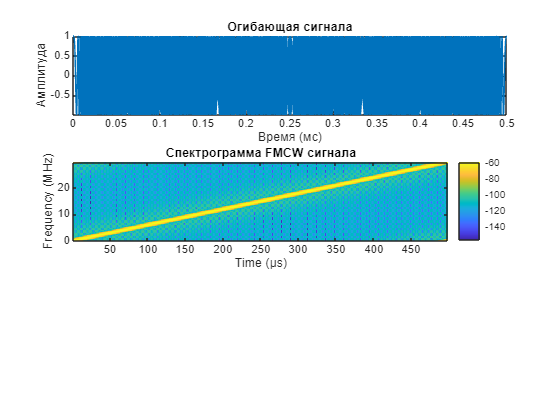

% Построение графиков
figure;

% График сигнала во времени
subplot(311);
plot(t * 1000, real(sig)); % Время в миллисекундах
xlabel('Время (мс)');
ylabel('Амплитуда');
title('Огибающая сигнала');
grid on;
axis tight;

% Спектрограмма
subplot(312);
window_length = 64;
overlap = 32;
nfft = 128;
spectrogram(sig, window_length, overlap, nfft, fs, 'yaxis');
title('Спектрограмма FMCW сигнала');
colorbar;


% % Спектрограмма с другими параметрами
% subplot(313); 
% spectrogram(sig, 32, 16, 32, waveformSamplingRate, 'yaxis');
% title('Спектрограмма FMCW сигнала');
% colorbar;


## Описание сценария

% Платформа неподвижного радара
azimuth = 0; % азимут (вращение вокруг Z, 0° — вдоль оси X)
elevation = 30; % угол места (вращение вокруг Y, положительный вверх)
roll  = 0;

% матрица поворота ZYX (yaw-pitch-roll)
Rz = @(a)[cosd(a) -sind(a) 0;
          sind(a) cosd(a)  0;
          0       0        1];
Ry = @(a)[cosd(a) 0 sind(a);
          0       1 0;
          -sind(a) 0 cosd(a)];
Rx = @(a)[1 0       0;
          0 cosd(a) -sind(a);
          0 sind(a) cosd(a)];
% Общая матрица
orientationAxes = Rz(azimuth) * Ry(-elevation) * Rx(roll);

% Платформа радара
radarPlatform = phased.Platform( ...
    'InitialPosition', [0; 0; 0], ...
    'Velocity', [0; 0; 0], ...
    'OrientationAxes', orientationAxes);


% Параметры целей
numb_targ = 3;
position_trgts = [[500,   0,  100];   % x, y, z
                  [350, 200, 350];
                  [1000, 500, 600]];
direction_trgts = [[ 180,  0];      % azimuth, elevation
                   [ -45,   30];
                   [ -30,   0]]; 
flight_speed_trgts = [10; 15; 25];      % Скорости

rcs_trgts = [0.5; 0.01; 1];

% Описание целей
targets = {};

for iter = 1:numb_targ
    % ЭПР цели
    mrcs = db2pow(rcs_trgts(iter));
    targetRCS = phased.RadarTarget('MeanRCS', mrcs, ...
                    'PropagationSpeed', c, 'OperatingFrequency', fc);
    % Скорость в декартовых координатах
    init_speed = [cosd(direction_trgts(iter, 1)) * cosd(direction_trgts(iter, 2)) * flight_speed_trgts(iter); ...
                  sind(direction_trgts(iter, 1)) * cosd(direction_trgts(iter, 2)) * flight_speed_trgts(iter); ...
                  sind(direction_trgts(iter, 2)) * flight_speed_trgts(iter)]
    % Положение
    init_pos = [position_trgts(iter, 1); position_trgts(iter, 2); position_trgts(iter, 3)]
    
    % Платформа цели
    targetMotion = phased.Platform('InitialPosition', init_pos, ...
                                   'Velocity', init_speed);
    
    % Добавление цели в список
    targets{end+1} = {targetRCS, targetMotion};
end

init_speed =    -10
     0
     0


init_pos =    500
     0
   100


init_speed =     9.1856
   -9.1856
    7.5000


init_pos =    350
   200
   350


init_speed =    21.6506
  -12.5000
         0


init_pos =         1000
         500
         600


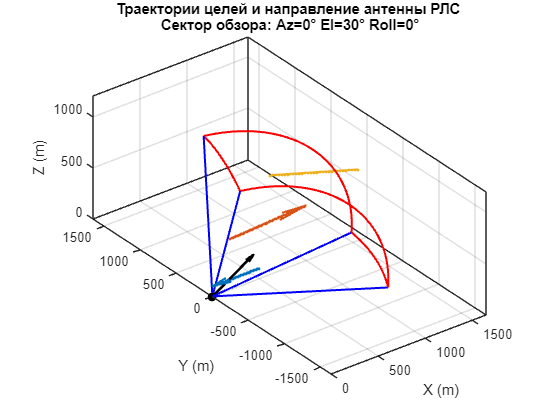

% Параметры моделирования

T = 1;     % шаг обновления (с)
N = km*N_Chirp;    % количество шагов
colors = lines(numb_targ);


% ---------------- ОТРИСОВКА ----------------
figure('Color','w')
hold on;
grid on;
axis equal
xlabel('X (m)')
ylabel('Y (m)')
zlabel('Z (m)')
title(sprintf('Траектории целей и направление антенны РЛС \nСектор обзора: Az=%.0f° El=%.0f° Roll=%.0f°',azimuth,elevation,roll));
% границы просмотра
xlim([0 R_max]*1.1);
ylim([-R_max R_max]*1.1);
zlim([0 R_max*0.8]);
view(3);
box on;


% Отображение зоны РЛС
L = 500; % длина стрелки  
dx = L * cosd(elevation) * cosd(azimuth);
dy = L * cosd(elevation) * sind(azimuth);
dz = L * sind(elevation);

quiver3(0,0,0, dx, dy, dz, 0, 'k', 'LineWidth', 2, 'MaxHeadSize', 0.5);

% углы по краям сектора
azHalf = azWidth/2;
elHalf = elWidth/2;
azCorners = [-azHalf, azHalf, azHalf, -azHalf];
elCorners = [-elHalf, -elHalf, elHalf, elHalf];



% центр
plot3(0,0,0,'ko','MarkerFaceColor','k','MarkerSize',6);

% 1) рёбра от центра к дальним углам
for k = 1:4
    [x,y,z] = sph2cart(deg2rad(azCorners(k)), deg2rad(elCorners(k)), R_max);
    p = orientationAxes * [x;y;z];
    plot3([0 p(1)], [0 p(2)], [0 p(3)], 'b-', 'LineWidth',1.5);
end

% 2) дуги по азимуту (при фиксированных el = ±elHalf)
N = 50;
az = linspace(-azHalf, azHalf, N);
for e = [-elHalf, elHalf]
    [x,y,z] = sph2cart(deg2rad(az), deg2rad(e)*ones(1,N), R_max*ones(1,N));
    P = orientationAxes * [x;y;z];
    plot3(P(1,:), P(2,:), P(3,:), 'r-', 'LineWidth',1.5);
end

% 3) дуги по углу места (при фиксированных az = ±azHalf)
el = linspace(-elHalf, elHalf, N);
for a = [-azHalf, azHalf]
    [x,y,z] = sph2cart(deg2rad(a)*ones(1,N), deg2rad(el), R_max*ones(1,N));
    P = orientationAxes * [x;y;z];
    plot3(P(1,:), P(2,:), P(3,:), 'r-', 'LineWidth',1.5);
end


% Отрисовка всех целей
for trg = 1:numb_targ
    posmat = zeros(3,N);
    for n = 1:N
        target = targets{trg}{2};
        Pos = target(T);
        posmat(:,n) = Pos;
    end
    reset(target);
    plot3(posmat(1,:), posmat(2,:), posmat(3,:), '.', 'Color', colors(trg,:)); 
    hold on

    % стрелка от первой до последней точки
    startP = posmat(:,1);             
    endP   = posmat(:,end);           
    v      = endP - startP;           

    quiver3(startP(1), startP(2), startP(3), ...
            v(1), v(2), v(3), 0, ... % scale=0 - без нормировки
            'Color', colors(trg,:), ...
            'MaxHeadSize', 2, 'LineWidth', 1.5);
end

## Моделирование

specanalyzer = spectrumAnalyzer('SampleRate', fs, ...
    'Method', 'welch', 'AveragingMethod', 'running', ...
    'PlotAsTwoSidedSpectrum', true, 'FrequencyResolutionMethod', 'rbw', ...
    'Title', 'Spectrum for received and dechirped signal', ...
    'ShowLegend', true);

rng(2025);

accumTime = 1*Tm;
propagation_time = range2time(R_max);
N_sweep = round(accumTime / propagation_time)

N_sweep = 50

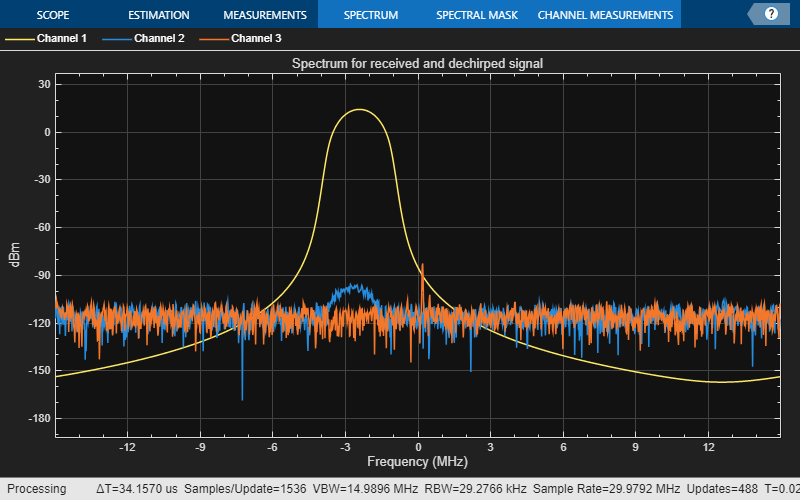


xr = complex(zeros(waveform.SampleRate * waveform.SweepTime * N_Chirp, N_sweep));
% radar_pos_all = zeros(3, N_sweep);
tgt_pos_all = zeros(3, numb_targ, N_sweep);

for m = 1:N_sweep
    % Обновление положения радара
    [radar_pos, radar_vel] = radarPlatform(waveform.SweepTime);
    % radar_pos_all(:, m) = radar_pos;

    % Передача FMCW-сигнала
    sig = waveform();
    txsig = transmitter(sig);

    % Суммарный принятый сигнал от всех целей
    rx_total = complex(zeros(size(txsig)));

    for trg = 1:numb_targ
        % Обновление положения цели
        target = targets{trg}{2};
        [tgt_pos, tgt_vel] = target(waveform.SweepTime);
        tgt_pos_all(:, trg, m) = tgt_pos;

        % Пропуск через канал
        txsig_tgt = channel(txsig, radar_pos, tgt_pos, radar_vel, tgt_vel);

        % Отражение от цели
        txsig_tgt = targets{trg}{1}(txsig_tgt);

        % Прием Суммируем сигнал
        rx_total = rx_total + receiver(txsig_tgt);
    end

    % Дечирп
    xr(:,m) = dechirp(rx_total, sig);

    % Визуализация спектра
    specanalyzer([sig rx_total xr(:,m)]);

end

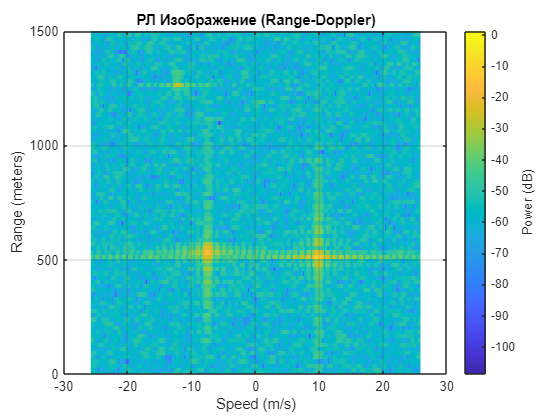

% Создание раиолокационного кадра
rngdopresp = phased.RangeDopplerResponse('PropagationSpeed',c,...
    'DopplerOutput','Speed','OperatingFrequency',fc,'SampleRate',fs,...
    'RangeMethod','FFT','SweepSlope',sweepSlope,...
    'RangeFFTLengthSource','Property','RangeFFTLength',4096,...
    'DopplerFFTLengthSource','Property','DopplerFFTLength',1024);

clf;

plotResponse(rngdopresp, xr);                     % Грфик Расстояние и доплеровское смещение

axis([-flightSpeed_max flightSpeed_max 0 R_max])
grid on;
title('РЛ Изображение (Range-Doppler)');

% Оценка высоты и скорости за период синтезирования
climVals = clim;

if strcmp(modulationType, 'Triangle')
    fbu_rng = rootmusic(pulsint(xr(:,1:2:end),'coherent'),1,fs)
    fbd_rng = rootmusic(pulsint(xr(:,2:2:end),'coherent'),1,fs)
    rng_est = beat2range([fbu_rng fbd_rng],sweepSlope,c)
    fd = -(fbu_rng+fbd_rng)/2
    v_est = dop2speed(fd,lambda)/2
else
    % Dn = fix(fs/(2*fb_max));
    % for m = size(xr,2):-1:1
    %     xr_d(:,m) = decimate(xr(:,m),Dn,'FIR');
    % end
    % fs_d = fs/Dn;
    fb_rng = rootmusic(pulsint(xr,'coherent'),1,fs)
    rng_est = beat2range(fb_rng,sweepSlope,c)
    peak_loc = val2ind(rng_est,c/(fs*2));
    fd = -rootmusic(xr(peak_loc,:),1,1/Tm);
    v_est = dop2speed(fd,lambda)
end

fb_rng = 1.8086e+05

rng_est = 452.4592

v_est = -4.0941

% Параметры FFT для оценки сигнала целей
RangeFFTLength   = 2048; 
DopplerFFTLength = 512;

% FFT по дальности (по строкам xr)
R = fft(xr, RangeFFTLength, 1);

% FFT по доплеру (по столбцам) — центрирование
RD = fftshift( fft(R, DopplerFFTLength, 2), 2 );

% амплитуда (модуль)
RDmag = abs(RD);

% векторы частот/диапазонов
fs_r = fs;
f_range = (0:RangeFFTLength-1)' * (fs / RangeFFTLength); % частоты биения
rangeVec = beat2range(f_range, sweepSlope, c);        % метры

PRF = 1 / T_sweep;
f_doppler = (-DopplerFFTLength/2 : DopplerFFTLength/2-1) * (PRF / DopplerFFTLength);
vVec = dop2speed(f_doppler, lambda);  


BW = imregionalmax(RDmag);            
threshold = max(RDmag(:)) * 0.2;     
candidates = find(BW & (RDmag > threshold));


[vals, idxs] = sort(RDmag(candidates), 'descend');
Npeaks = min(10, numel(vals)); % выбор числа пиков
sel = candidates(idxs(1:Npeaks));


[rowInd, colInd] = ind2sub(size(RDmag), sel);
for k = 1:numel(sel)
    rbin = rowInd(k);
    dbin = colInd(k);
    fb = f_range(rbin);
    rng_found = beat2range(fb, sweepSlope, c);
    fd = f_doppler(dbin);
    v_found = dop2speed(fd, lambda);
    fprintf('Peak %d: range = %.1f m, speed = %.2f m/s\n', k, rng_found, v_found);
end

Peak 1: range = 512.7 m, speed = -19.57 m/s
Peak 2: range = 549.3 m, speed = 14.93 m/s
Peak 3: range = 512.7 m, speed = -22.60 m/s
Peak 4: range = 512.7 m, speed = -16.75 m/s
